# Circuit 1-Circuit 2 DYS

#### This file analyzes 1.3a and 1.3b

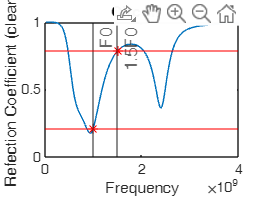

% 
% Circuit 1
% 1.3a
% 

f0=10^9;

N=201;
f=0:4*f0/N:4*f0;
b=2*pi.*f./f0;

Z0=50;
ZL=100-1i./(2*pi.*f*2*10^-12); %load
Z1=zeta(ZL,b,0.2); %down branch
Z2=zeta(0,b,0.13); %shorted branch
Z12=parallel(Z1,Z2); %combination
Z3=zeta(Z12,b,0.1);
Zin=parallel(Z3,-1i./(2*pi.*f*2.7*10^-12));

gamma=(Zin-Z0)./(Zin+Z0);

plot(f,abs(gamma));
hold on
title("Circuit 1")
ylabel("Refection Coefficient (clean)")
xlabel("Frequency")
xline(f0,"-","F0")
xline(1.5*f0,"-","1.5F0")
plot(f(51),abs(gamma(51)),"r*")
yline(abs(gamma(51)),"r")
plot(f(77),abs(gamma(77)),"r*")
yline(abs(gamma(77)),"r")
hold off

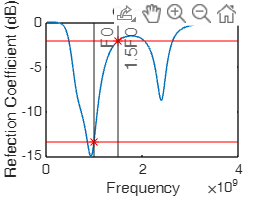


plot(f,db(abs(gamma)))
hold on
title("Circuit 1")
ylabel("Refection Coefficient (dB)")
xlabel("Frequency")
xline(f0,"-","F0")
xline(1.5*f0,"-","1.5F0")
plot(f(51),db(abs(gamma(51))),"r*")
yline(db(abs(gamma(51))),"r")
plot(f(77),db(abs(gamma(77))),"r*")
yline(db(abs(gamma(77))),"r")
hold off

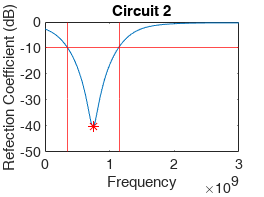

% 
% Circuit 2
% 1.3b
% 

f0=10^9;

N=201;
f=0:3*f0/N:3*f0;

b=2*pi.*f./f0;

Z0=50;
ZL=Z0; %load
Z1=Z0; %TM with load

Z2=parallel(Z1,-98.45i); %open branch
Z3=zeta(Z2,b,0.125,101.6);

Z4=parallel(Z3,-43.6i);% open branch
Z5=zeta(Z4,b,0.125,101.6);

Zin=parallel(Z5,-98.45i);%open branch

gamma=(Zin-Z0)./(Zin+Z0);
SWR=(1+abs(gamma))./(1-abs(gamma));

plot(f,db(abs(gamma)))
hold on
title("Circuit 2")
ylabel("Refection Coefficient (dB)")
xlabel("Frequency")
yline(-10,"r")
xline(0.35*f0,"r")
xline(1.15*f0,"r")
plot(f(51),db(abs(gamma(51))),"r*")
hold off 

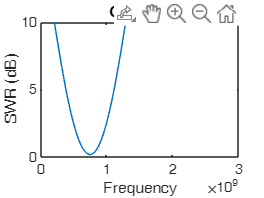


plot(f,db(SWR))
hold on
title("Circuit 2")
ylabel("SWR (dB)")
xlabel("Frequency")
ylim([0 10])
xlim([0 3*f0])
hold off

function z=zeta(ZL,b,l,Z0)
    if nargin<4
        Z0=50;
    end
    z=Z0*(ZL+1i*Z0.*tan(b.*l))./(Z0+1i*ZL.*tan(b.*l));
end

function zp=parallel(z1,z2)
    zp=1./((1./z1)+(1./z2));
end